## RP-Multibody

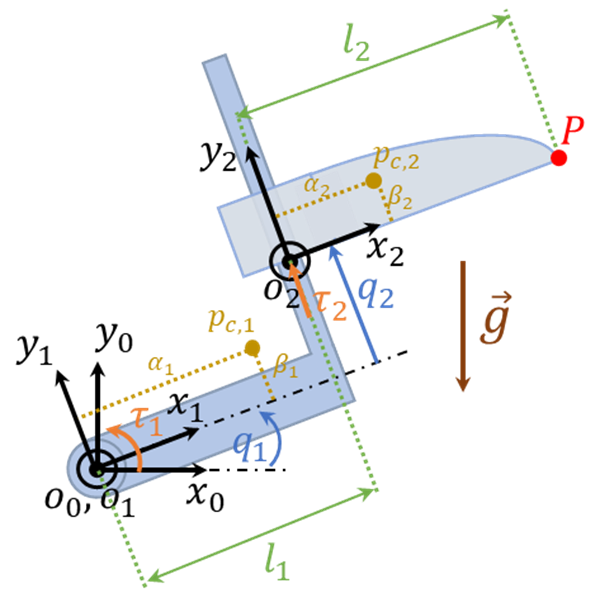

clear all; close all; clc

% Initialize symbolic variables
syms q_1 q_2
syms qd_1 qd_2
syms qdd_1 qdd_2
syms m_1 m_2
syms I_xx_1 I_yy_1 I_zz_1 I_xx_2 I_yy_2 I_zz_2
syms l_1 l_2 g
syms alf_1 bet_1 alf_2 bet_2
syms c_2

% Create symbolic vectors
q = [q_1; q_2];
qd = [qd_1; qd_2];
qdd = [qdd_1; qdd_2];

% Inertial parameters
m = [m_1; m_2];

I_k{1} = [I_xx_1    0   0;
          0     I_yy_1  0;
          0     0       I_zz_1];

I_k{2} = [I_xx_2    0   0;
          0     I_yy_2  0;
          0     0       I_zz_2];

p_c_1 = [alf_1; bet_1; 0];
p_c_2 = [alf_2; bet_2; 0];

#### 3. Orientation kinematics

% orientation of o1_x1_y1_z1 relative to the fixed frame o0_x0_y0_z0
R_1_0 = Rz_theta(q_1,3)

$$R\_1\_0 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_2_1 = eye(3)

R_2_1 =      1     0     0
     0     1     0
     0     0     1


R_0{1} = R_1_0;
R_0{2} = R_1_0 * R_2_1;
disp(R_0{1})

$$\left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

disp(R_0{2})

$$\left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

#### 4. Translational kinematics

% coordinates of o2_x2_y2_z2 expressed in the fixed frame of o1_x1_y1_z1
o_2_1 = [l_1; q_2; 0]

$$o\_2\_1 = \left(\begin{array}{c} l_{1}\\ q_{2}\\ 0 \end{array}\right)$$

% coordinates of o2_x2_y2_z2 expressed in the fixed frame of o0_x0_y0_z0
o_2_0 = R_1_0 * o_2_1 

$$o\_2\_0 = \left(\begin{array}{c} l_{1}\,\cos\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right)\\ q_{2}\,\cos\left(q_{1}\right)+l_{1}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

% coordinates of the end-point expressed in the fixed frame o0_x0_y0_z0
P_0 = o_2_0 + [l_2; 0; 0]

$$P\_0 = \left(\begin{array}{c} l_{2}+l_{1}\,\cos\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right)\\ q_{2}\,\cos\left(q_{1}\right)+l_{1}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

#### 5. Expressing the coordinates of the center of masses of the links into the fixed frame $o_{0}x_{0}y_{0}z_{0}$

% relative to frame of o0x0y0z0
p_c_0{1} =  R_1_0 * p_c_1;
disp(p_c_0{1})

$$\left(\begin{array}{c} {\mathrm{alf}}_{1}\,\cos\left(q_{1}\right)-{\mathrm{bet}}_{1}\,\sin\left(q_{1}\right)\\ {\mathrm{bet}}_{1}\,\cos\left(q_{1}\right)+{\mathrm{alf}}_{1}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

p_c_0{2} = o_2_0 + p_c_2;
disp(p_c_0{2})

$$\left(\begin{array}{c} {\mathrm{alf}}_{2}+l_{1}\,\cos\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right)\\ {\mathrm{bet}}_{2}+q_{2}\,\cos\left(q_{1}\right)+l_{1}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

#### 6. Computation of translational velocities of the center of masses expressed in $o_{0}x_{0}y_{0}z_{0}$

pd_c_0{1} = jacobian(p_c_0{1},q) * qd;
disp(pd_c_0{1})

$$\left(\begin{array}{c} -{\mathrm{qd}}_{1}\,\left({\mathrm{bet}}_{1}\,\cos\left(q_{1}\right)+{\mathrm{alf}}_{1}\,\sin\left(q_{1}\right)\right)\\ {\mathrm{qd}}_{1}\,\left({\mathrm{alf}}_{1}\,\cos\left(q_{1}\right)-{\mathrm{bet}}_{1}\,\sin\left(q_{1}\right)\right)\\ 0 \end{array}\right)$$

pd_c_0{2} = jacobian(p_c_0{2},q) * qd;
disp(pd_c_0{2})

$$\left(\begin{array}{c} -{\mathrm{qd}}_{1}\,\left(q_{2}\,\cos\left(q_{1}\right)+l_{1}\,\sin\left(q_{1}\right)\right)-{\mathrm{qd}}_{2}\,\sin\left(q_{1}\right)\\ {\mathrm{qd}}_{1}\,\left(l_{1}\,\cos\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right)\right)+{\mathrm{qd}}_{2}\,\cos\left(q_{1}\right)\\ 0 \end{array}\right)$$

#### 7. Computation of the translational kinetic energy

K_t_1 = simplify(0.5*m(1)*transpose(pd_c_0{1})*pd_c_0{1})

$$K\_t\_1 = \frac{m_{1}\,{{\mathrm{qd}}_{1}}^{2}\,\left({{\mathrm{alf}}_{1}}^{2}+{{\mathrm{bet}}_{1}}^{2}\right)}{2}$$

K_t_2 = simplify(0.5*m(2)*transpose(pd_c_0{2})*pd_c_0{2})

$$K\_t\_2 = \frac{m_{2}\,\left({l_{1}}^{2}\,{{\mathrm{qd}}_{1}}^{2}+2\,l_{1}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}+{q_{2}}^{2}\,{{\mathrm{qd}}_{1}}^{2}+{{\mathrm{qd}}_{2}}^{2}\right)}{2}$$

K_t = K_t_1 + K_t_2

$$K\_t = \frac{m_{2}\,\left({l_{1}}^{2}\,{{\mathrm{qd}}_{1}}^{2}+2\,l_{1}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}+{q_{2}}^{2}\,{{\mathrm{qd}}_{1}}^{2}+{{\mathrm{qd}}_{2}}^{2}\right)}{2}+\frac{m_{1}\,{{\mathrm{qd}}_{1}}^{2}\,\left({{\mathrm{alf}}_{1}}^{2}+{{\mathrm{bet}}_{1}}^{2}\right)}{2}$$

#### 8. Computation of the angular velocities of the coordinate frames "glued" to the links relative to the fixed frame $o_{0}x_{0}y_{0}z_{0}$

for k = 1 : 2
    Rd_0{k} = diff(R_0{k},q_1)*qd_1 + diff(R_0{k},q_2)*qd_2;    % Chain rule

    S_w_0{k} = simplify(Rd_0{k} * transpose(R_0{k}));
    w_0{k} = [S_w_0{k}(3,2); S_w_0{k}(1,3); S_w_0{k}(2,1)];
end





#### 9. Computation of the rotational kinetic energy

% TODO

